v = VideoReader("Turkey Video.mp4")

v =   VideoReader with properties:

   General Properties:
            Name: 'Turkey Video.mp4'
            Path: 'C:\Users\backupadmin\Documents\ImageProcessingCoursera\Image Processing for Engineering and Science\Data\MathWorks Images'
        Duration: 25.2333
     CurrentTime: 0.0333
       NumFrames: 757

   Video Properties:
           Width: 1080
          Height: 1080
       FrameRate: 30
    BitsPerPixel: 24
     VideoFormat: 'RGB24'




frameSum = im2double(read(v,1));
for idx = 2:v.NumFrames
    frameSum = frameSum + im2double(read(v,idx));
end

aveFrame = frameSum/v.NumFrames

aveFrame = aveFrame(:,:,1) =

    0.3319    0.3416    0.3421    0.3311    0.3221    0.3196    0.3228    0.3262    0.3299    0.3205    0.3180    0.3221    0.3241    0.3201    0.3108    0.2988    0.3037    0.3135    0.3219    0.3238    0.3139    0.3041    0.3117    0.3229    0.3284    0.3408    0.3400    0.3180    0.2954    0.2911    0.3008    0.3136    0.3312    0.3234    0.2978    0.2879    0.2930    0.3046    0.3123    0.3145    0.3167    0.3178    0.3167    0.3148    0.3158    0.3183    0.3348    0.3676    0.4098    0.4361    0.4409    0.4491    0.4686    0.4775    0.4927    0.5138    0.5387    0.5799    0.6266    0.6517    0.6518    0.6287    0.5802    0.5394    0.5273    0.5272    0.5316    0.5376    0.5408    0.5376    0.5075    0.4799    0.4892    0.5191    0.5501    0.5853    0.6192    0.6407    0.6463    0.6528    0.6603    0.6583    0.6608    0.6645    0.6696    0.6697    0.6511    0.6350    0.6238    0.5970    0.5479    0.4954    0.4276    0.4086    0.4477    0.4850    0.5277

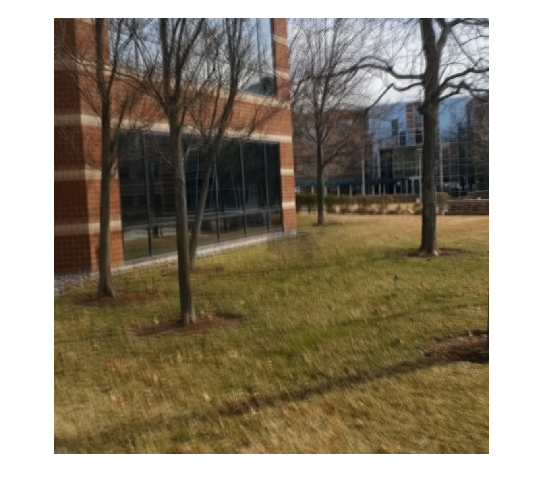

imshow(aveFrame)

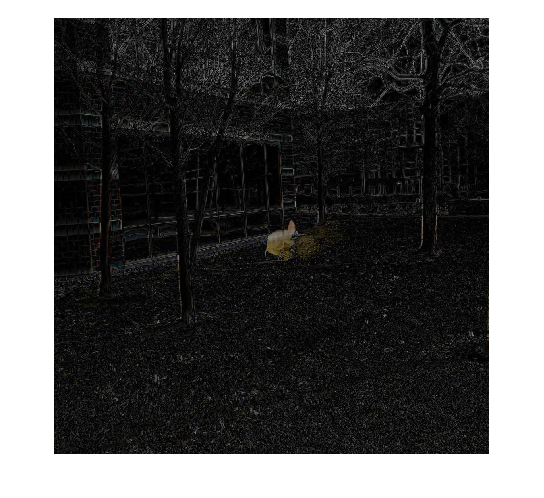

frame = read(v,290);
frame=im2double(frame);
background=aveFrame;
frameDiff = abs(frame-background);
imshow(frameDiff)

frameDiff = im2gray(frameDiff);

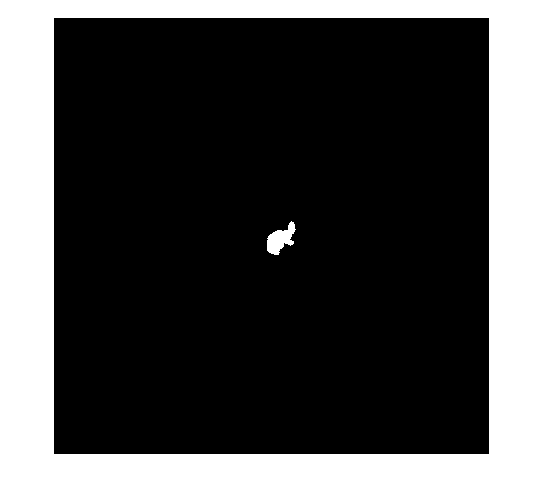

BW = segmentTurkey(frameDiff);
imshow(BW)

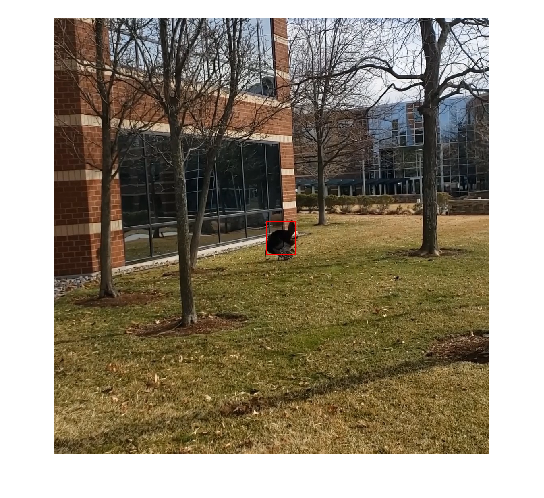

props = regionprops("table",BW,"BoundingBox");
turkeyBoxed = insertShape(frame,"rectangle",props.BoundingBox,"LineWidth",3,"Color","red");

imshow(turkeyBoxed)

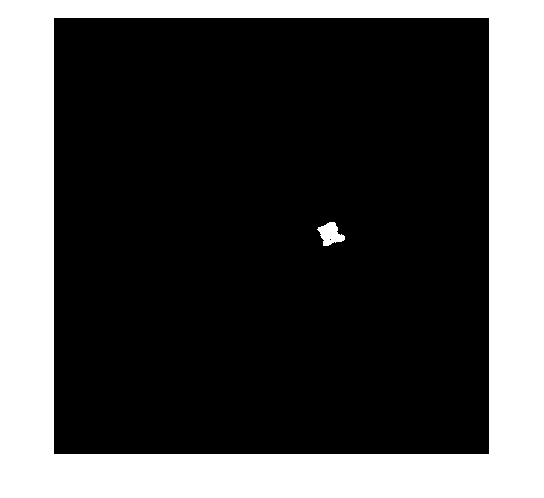

v2 = VideoWriter("Turkey Boxed Video.mp4","MPEG-4");
open(v2);

for idx = 1:v.NumFrames
    frame = read(v,idx);
    frame=im2double(frame);
    background=aveFrame;
    frameDiff = abs(frame-background);

    imshow(frameDiff)

    frameDiff = im2gray(frameDiff);

    BW = segmentTurkey(frameDiff);
    imshow(BW)
    props = regionprops("table",BW,"BoundingBox");
    turkeyBoxed = insertShape(frame,"rectangle",props.BoundingBox,"LineWidth",3,"Color","red");

    writeVideo(v2,turkeyBoxed);

end


close(v2);

v.CurrentTime = 0;